# EXERCISE A -- GUIDED STIFFNESS-METHOD TUTORIAL

Determine the horizontal displacement, vertical displacement and rotation at node 1. The horizontal beam is 3 m long; the right column is 4 m high and fixed at node 3. Node 2 is a rigid corner. At node 1, apply 18 kN left and 27 kN down.

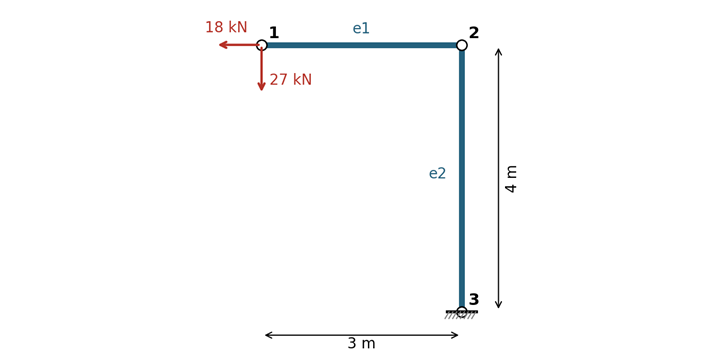

## 0. Prepare the workspace and display options

clear removes previous variables; clc clears the Command Window; close all closes earlier figures. Execute this section once at the START. showMatrices controls intermediate output, makePlots controls visualization, and deformationScale=0 requests automatic visual magnification. These switches do not change the structural solution.

clear; clc; close all;
format short g;
showMatrices = true;   % Show element matrices and assembled equations.
makePlots = true;      % Set false for numerical calculations only.
deformationScale = 0;  % Zero selects an automatic visual magnification.

## Exercise statement and modeling interpretation

Node 1: loaded free end; node 2: rigid corner; node 3: fixed base. Element 1 runs 1 -> 2 (right); element 2 runs 2 -> 3 (down).

## 1. Define material and section properties

PURPOSE: establish axial rigidity EA and bending rigidity EI. Convert 200 GPa to 200000 N/mm^2. All dimensions are entered in mm. A is cross-sectional area in mm^2; I is the second moment of area in mm^4 about the out-of-plane bending axis. Every member has the same properties, so scalar E, A and I are sufficient for these exercises.

E = 200e3;                 % N/mm^2 = 200 GPa
I = 300e6;                 % mm^4
A = 12.9e3;                % mm^2

## 2. Define node coordinates and member connectivity

PURPOSE: describe the frame as joints connected by straight members. Each row of nodes is [x y] in mm, and its row number is the node number. Each row of elements is [i j], and its row number is the element number. The i->j order defines local axes and signs; it does not change the physical frame if all associated local quantities are transformed consistently.

nodes = [0 4000;           % [x y], mm
         3000 4000;
         3000 0];
elements = [1 2; 2 3];

## 3. Associate each motion with a global equation number

PURPOSE: connect physical nodal motions with positions in the solution vector. dofMap(n,:)=[index_ux index_uy index_theta] at node n. For example, d(dofMap(n,1)) returns node n's horizontal displacement. Every global index appears once. Connectivity uses NODE numbers, whereas stiffness assembly uses DOF numbers: do not confuse these two lists.

dofMap = [1 2 3;           % Node 1: ux uy theta
          4 5 6;           % Node 2
          7 8 9];          % Node 3

## 4. Define the support restraints

PURPOSE: distinguish known motions from unknown motions. Node 3 is fixed: horizontal translation, vertical translation and rotation are all zero. Therefore constrain DOFs 7,8,9, leaving six unknown DOFs. prescribedValues has the same order as fixedDofs.

fixedDofs = [7 8 9];       % Fixed support: both translations and rotation.
prescribedValues = [0; 0; 0];

## 5. Define loads and their coordinate directions

PURPOSE: build a column vector of concentrated nodal actions. Force entries are in N; rotation-DOF entries are applied couples in N*mm. Node 1: 18 kN left -> F1=-18000 N; 27 kN down -> F2=-27000 N. The numbered DOF arrows in the figure are not extra applied loads. qLocal stores member loads per unit length; all are zero in this exercise. Stage 8 retains the general distributed-load procedure and gives zero vectors.

% POINT LOADS: 18 kN left and 27 kN down at node 1; no applied couple.
Fpoint = zeros(9,1);
Fpoint(dofMap(1,1)) = -18e3;
Fpoint(dofMap(1,2)) = -27e3;

% Uniform distributed loads in ELEMENT LOCAL axes: [qx qy], N/mm.
qLocal = zeros(2,2);       % No distributed loads in this exercise.
fprintf('EXERCISE A: displacements at node 1\n');

EXERCISE A: displacements at node 1


fprintf('Global signs: right/up/CCW positive. Internal units: N, mm, rad.\n');

Global signs: right/up/CCW positive. Internal units: N, mm, rad.


## 6. Determine element lengths, orientations and global DOF lists

PURPOSE: turn geometry into element information. For a member i->j: dx=xj-xi; dy=yj-yi; L=sqrt(dx^2+dy^2); c=dx/L; s=dy/L. c and s are direction cosines. Local x points from i to j; local y is 90 degrees counterclockwise from local x. edofs gives the six GLOBAL indices of this element in endpoint order. elementData stores one record per member, with named fields.

nNode = size(nodes,1);
nElem = size(elements,1);
nDof = 3*nNode;
assert(isequal(sort(dofMap(:)), (1:nDof).'), 'Check DOF numbering.');
elementData = struct([]);
for e = 1:nElem
    ij = elements(e,:);
    delta = nodes(ij(2),:) - nodes(ij(1),:);
    L = hypot(delta(1),delta(2));
    assert(L > 0,'An element must have nonzero length.');
    c = delta(1)/L;
    s = delta(2)/L;
    edofs = [dofMap(ij(1),:) dofMap(ij(2),:)];
    elementData(e).L = L;
    elementData(e).c = c;
    elementData(e).s = s;
    elementData(e).dofs = edofs;
    fprintf('\nElement %d: node %d -> %d, L = %.0f mm, c = %.1f, s = %.1f\n', ...
        e,ij(1),ij(2),L,c,s);
    fprintf('Element DOFs: '); fprintf('%d ',edofs); fprintf('\n');
end


Element 1: node 1 -> 2, L = 3000 mm, c = 1.0, s = 0.0


Element DOFs: 1 2 3 4 5 6 



Element 2: node 2 -> 3, L = 4000 mm, c = 0.0, s = -1.0


Element DOFs: 4 5 6 7 8 9 


% CHECK: rightward horizontal (c,s)=(1,0); upward vertical (0,1);
% downward vertical (0,-1). Reversing element order reverses its local axes.

## 7. Calculate the local stiffness and transform it to global axes

PURPOSE: combine axial and bending behavior in a common coordinate system. The included frameElement function gives the full 6-by-6 matrix. Its axial terms contain EA/L. Its bending terms contain 12EI/L^3, 6EI/L^2, 4EI/L and 2EI/L. A frame transmits bending moments as well as axial forces; a truss model would omit the bending behavior.

ELEMENT RELATION without member loading: qLocalEnd=kLocal*dLocal. dLocal=T*dGlobal; qGlobalEnd=T'*qLocalEnd. Consequently kGlobal=T'*kLocal*T. For each node [u;v]=[c s;-s c]*[ux;uy]; the z rotation is unchanged. Transforming forces with T' preserves virtual work in the two systems. MATLAB .' is transpose without complex conjugation.

for e = 1:nElem
    data = elementData(e);
    [kLocal,T] = frameElement(E,A,I,data.L,data.c,data.s);
    kGlobal = T.'*kLocal*T;
    elementData(e).kLocal = kLocal;
    elementData(e).T = T;
    elementData(e).kGlobal = kGlobal;
    if showMatrices
        fprintf('\nELEMENT %d STIFFNESS AND TRANSFORMATION\n',e);
        disp('Local stiffness kLocal:'); disp(kLocal);
        disp('Transformation T:'); disp(T);
        disp('Global stiffness T''*kLocal*T:'); disp(kGlobal);
    end
end


ELEMENT 1 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
      8.6e+05            0            0     -8.6e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
     -8.6e+05            0            0      8.6e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10



Transformation T:
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
      8.6e+05            0            0     -8.6e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
     -8.6e+05            0            0      8.6e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10




ELEMENT 2 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
     6.45e+05            0            0    -6.45e+05            0            0
            0        11250     2.25e+07            0       -11250     2.25e+07
            0     2.25e+07        6e+10            0    -2.25e+07        3e+10
    -6.45e+05            0            0     6.45e+05            0            0
            0       -11250    -2.25e+07            0        11250    -2.25e+07
            0     2.25e+07        3e+10            0    -2.25e+07        6e+10



Transformation T:
     0    -1     0     0     0     0
     1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0    -1     0
     0     0     0     1     0     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
        11250            0     2.25e+07       -11250            0     2.25e+07
            0     6.45e+05            0            0    -6.45e+05            0
     2.25e+07            0        6e+10    -2.25e+07            0        3e+10
       -11250            0    -2.25e+07        11250            0    -2.25e+07
            0    -6.45e+05            0            0     6.45e+05            0
     2.25e+07            0        3e+10    -2.25e+07            0        6e+10



% CHECK: both stiffness matrices are symmetric. Entries have mixed units
% because force/moment rows and translation/rotation columns coexist.

## 8. Convert distributed member loading into equivalent nodal actions

PURPOSE: represent continuous loading in the nodal equilibrium equations. For uniform local loads qx and qy (N/mm), the CONSISTENT load vector is: [qx*L/2; qy*L/2; qy*L^2/12; qx*L/2; qy*L/2; -qy*L^2/12]. It follows from integrating the load against the element shape functions. Two transverse forces alone can balance the resultant but do not preserve virtual work for arbitrary nodal rotations: include the end moments too. These equivalent actions are not the unknown support reactions. The global equivalent vector is fGlobal=T'*fLocal.

for e = 1:nElem
    L = elementData(e).L;
    T = elementData(e).T;
    qx = qLocal(e,1);
    qy = qLocal(e,2);
    fLocal = [qx*L/2; qy*L/2; qy*L^2/12;
              qx*L/2; qy*L/2; -qy*L^2/12];
    fGlobal = T.'*fLocal;
    elementData(e).fLocal = fLocal;
    elementData(e).fGlobal = fGlobal;
    if showMatrices
        fprintf('\nELEMENT %d EQUIVALENT NODAL LOADS\n',e);
        disp('Local order [Ni Vi Mi Nj Vj Mj]''; N and N*mm:'); disp(fLocal);
        disp('Same vector in global axes:'); disp(fGlobal);
    end
end


ELEMENT 1 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0




ELEMENT 2 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0



## 9. Assemble the global stiffness matrix and load vector

PURPOSE: combine member equations while enforcing joint compatibility. K begins as an nDof-by-nDof zero matrix; F begins with concentrated loads. K(edofs,edofs) selects the element's 6-by-6 contribution within the frame. ADD each transformed matrix and load vector; do not overwrite existing contributions at a shared joint. Shared nodal translations and rotations enforce compatibility between connected members and their rigid joint. The full K has rigid-body modes before support restraints are applied. We therefore solve the reduced restrained system, not K*d=F directly.

K = zeros(nDof);
F = Fpoint;
for e = 1:nElem
    edofs = elementData(e).dofs;
    K(edofs,edofs) = K(edofs,edofs) + elementData(e).kGlobal;
    F(edofs) = F(edofs) + elementData(e).fGlobal;
end
if showMatrices
    disp('ASSEMBLED K:'); disp(K);
    disp('ASSEMBLED F:'); disp(F);
end

ASSEMBLED K:
      8.6e+05            0            0     -8.6e+05            0            0            0            0            0
            0        26667        4e+07            0       -26667        4e+07            0            0            0
            0        4e+07        8e+10            0       -4e+07        4e+10            0            0            0
     -8.6e+05            0            0   8.7125e+05            0     2.25e+07       -11250            0     2.25e+07
            0       -26667       -4e+07            0   6.7167e+05       -4e+07            0    -6.45e+05            0
            0        4e+07        4e+10     2.25e+07       -4e+07      1.4e+11    -2.25e+07            0        3e+10
            0            0            0       -11250            0    -2.25e+07        11250            0    -2.25e+07
            0            0            0            0    -6.45e+05            0            0     6.45e+05            0
            0            0            0    

ASSEMBLED F:
      -18000
      -27000
           0
           0
           0
           0
           0
           0
           0



## 10. Partition the equations using the support conditions

PURPOSE: solve only for motions that are genuinely unknown. Let f mean free and c mean constrained: Kff*df+Kfc*dc=Ff, so Kff*df=Ff-Kfc*dc. setdiff finds all DOFs not listed in fixedDofs. Initialize the complete d, insert prescribed support motions dc, and extract Kff and rhs in freeDofs order. Here dc=0; retaining Kfc*dc also supports imposed nonzero motions.

% Partition: Kff*df + Kfc*dc = Ff, where dc contains known displacements.
% Backslash solves the system directly; an explicit inverse is unnecessary.
freeDofs = setdiff(1:nDof,fixedDofs);
d = zeros(nDof,1);
d(fixedDofs) = prescribedValues;
Kff = K(freeDofs,freeDofs);
rhs = F(freeDofs) - K(freeDofs,fixedDofs)*d(fixedDofs);

## 11. Check stability and solve for the free displacements

PURPOSE: obtain the unique elastic solution of the restrained frame. K must be symmetric. Kff should be positive definite for this stable model; chol returns a nonzero flag if that property is absent. MATLAB backslash solves the linear system without explicitly forming inv(Kff). Insert the solved free motions into their original positions in d.

assert(norm(K-K.','fro') <= 1e-12*norm(K,'fro'), 'K must be symmetric.');
[~,cholFlag] = chol(Kff);
assert(cholFlag == 0, 'The restrained frame is unstable or incorrectly assembled.');
d(freeDofs) = Kff \ rhs;

if showMatrices
    fprintf('\nASSEMBLED SYSTEM\n');
    disp('Full K (mixed force/moment and translation/rotation units):'); disp(K);
    disp('Equivalent global load vector F:'); disp(F);
    disp('Free DOFs, in reduced-system order:'); disp(freeDofs);
    disp('Reduced stiffness Kff:'); disp(Kff);
    disp('Reduced right-hand side:'); disp(rhs);
end


ASSEMBLED SYSTEM


Full K (mixed force/moment and translation/rotation units):
      8.6e+05            0            0     -8.6e+05            0            0            0            0            0
            0        26667        4e+07            0       -26667        4e+07            0            0            0
            0        4e+07        8e+10            0       -4e+07        4e+10            0            0            0
     -8.6e+05            0            0   8.7125e+05            0     2.25e+07       -11250            0     2.25e+07
            0       -26667       -4e+07            0   6.7167e+05       -4e+07            0    -6.45e+05            0
            0        4e+07        4e+10     2.25e+07       -4e+07      1.4e+11    -2.25e+07            0        3e+10
            0            0            0       -11250            0    -2.25e+07        11250            0    -2.25e+07
            0            0            0            0    -6.45e+05            0            0     6.45e+05          

Equivalent global load vector F:
      -18000
      -27000
           0
           0
           0
           0
           0
           0
           0



Free DOFs, in reduced-system order:
     1     2     3     4     5     6



Reduced stiffness Kff:
      8.6e+05            0            0     -8.6e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
     -8.6e+05            0            0   8.7125e+05            0     2.25e+07
            0       -26667       -4e+07            0   6.7167e+05       -4e+07
            0        4e+07        4e+10     2.25e+07       -4e+07      1.4e+11



Reduced right-hand side:
      -18000
      -27000
           0
           0
           0
           0



## 12. Recover reactions and organize the nodal displacements

PURPOSE: substitute the solved motions into the FULL unreduced equations. R=K*d-F gives support reactions at constrained DOFs and numerical zeros at free DOFs. F must include equivalent member loads as well as point loads. d(dofMap.') gathers entries in node order; reshape and transpose produce one row per node: [ux uy theta]. The table reports mm, mm and radians.

% R = K*d-F includes distributed loads through their assembled equivalent
% nodal vector. Free-DOF entries should be numerical roundoff only.
R = K*d - F;
nodalD = reshape(d(dofMap.'),3,nNode).';
nodalR = reshape(R(dofMap.'),3,nNode).';
displacementTable = table((1:nNode).',dofMap(:,1),dofMap(:,2),dofMap(:,3), ...
    nodalD(:,1),nodalD(:,2),nodalD(:,3), ...
    'VariableNames',{'Node','DOF_ux','DOF_uy','DOF_theta','ux_mm','uy_mm','theta_rad'});
fprintf('\nNODAL DISPLACEMENTS (positive right/up/CCW)\n');


NODAL DISPLACEMENTS (positive right/up/CCW)


disp(displacementTable);

    Node    DOF_ux    DOF_uy    DOF_theta     ux_mm      uy_mm      theta_rad
    ____    ______    ______    _________    _______    ________    _________

     1        1         2           3        -17.221     -27.492    0.009825 
     2        4         5           6          -17.2    -0.04186      0.0078 
     3        7         8           9              0           0           0 



## 13. Display the support reactions in kN and kN*m

PURPOSE: extract support-node actions and convert from internal units. Divide N by 1000 and N*mm by 1000000. Reactions act FROM the support ON the frame; positive means right/up/CCW. A downward vertical pin reaction means that the support must hold the frame down: uplift demand on anchorage. Pin moment entries are free-DOF residuals and should be numerical zero.

supportNodes = find(any(ismember(dofMap,fixedDofs),2));
reactionTable = table(supportNodes,nodalR(supportNodes,1)/1e3, ...
    nodalR(supportNodes,2)/1e3,nodalR(supportNodes,3)/1e6, ...
    'VariableNames',{'Node','Rx_kN','Ry_kN','Mz_kNm'});
fprintf('SUPPORT REACTIONS (positive right/up/CCW)\n');

SUPPORT REACTIONS (positive right/up/CCW)


disp(reactionTable);

    Node    Rx_kN    Ry_kN    Mz_kNm
    ____    _____    _____    ______

     3       18       27       -153 



## 14. Recover axial force, shear force and moment at each member end

PURPOSE: obtain the actions applied TO each member at its two ends. Extract its six global displacements; transform them by dLocal=T*dGlobal. Then qEnd=kLocal*dLocal-fLocal. Subtracting the consistent load vector accounts for load-induced fixed-end actions. kLocal*dLocal alone is wrong for a member with distributed loading. Order is [Ni Vi Mi Nj Vj Mj]; both end moments are positive CCW. These endpoint actions use a different convention from opposite-face signs often chosen for internal force diagrams; do not equate their signs directly.

endForcesLocal = zeros(nElem,6);
for e = 1:nElem
    data = elementData(e);
    dLocal = data.T*d(data.dofs);
    % Subtract the consistent load vector. kLocal*dLocal alone gives the
    % wrong end actions when the member carries distributed loading.
    qEnd = data.kLocal*dLocal - data.fLocal;
    elementData(e).dLocal = dLocal;
    endForcesLocal(e,:) = qEnd.';
end
endForceTable = table((1:nElem).',endForcesLocal(:,1)/1e3, ...
    endForcesLocal(:,2)/1e3,endForcesLocal(:,3)/1e6, ...
    endForcesLocal(:,4)/1e3,endForcesLocal(:,5)/1e3,endForcesLocal(:,6)/1e6, ...
    'VariableNames',{'Element','Ni_kN','Vi_kN','Mi_kNm','Nj_kN','Vj_kN','Mj_kNm'});
fprintf('LOCAL END ACTIONS applied TO each member, in its local axes\n');

LOCAL END ACTIONS applied TO each member, in its local axes


fprintf('Order: [Ni Vi Mi Nj Vj Mj]; moments positive CCW at both ends.\n');

Order: [Ni Vi Mi Nj Vj Mj]; moments positive CCW at both ends.


fprintf('These are end actions, not a bending-diagram sign convention.\n');

These are end actions, not a bending-diagram sign convention.


disp(endForceTable);

    Element    Ni_kN    Vi_kN      Mi_kNm      Nj_kN    Vj_kN    Mj_kNm
    _______    _____    _____    __________    _____    _____    ______

       1        -18      -27     5.9605e-14      18      27        -81 
       2         27      -18             81     -27      18       -153 



## 15. Check free-DOF equilibrium and whole-frame static balance

PURPOSE: verify sum(Fx)=0, sum(Fy)=0 and sum(M_origin)=0. A force at [x,y] contributes moment x*Fy-y*Fx. Here a uniform load is represented by its physical resultant at the member centroid, independently of the equivalent nodal loading used to solve the system. Numerical roundoff is normal; assert stops if a tolerance is exceeded.

% Sum the physical forces/moments (distributed loads at their centroids).
% This independently checks the assembled consistent-load vector.
pointNodal = reshape(Fpoint(dofMap.'),3,nNode).';
balance = [sum(pointNodal(:,1)+nodalR(:,1));
           sum(pointNodal(:,2)+nodalR(:,2));
           sum(pointNodal(:,3)+nodalR(:,3) ...
             + nodes(:,1).*(pointNodal(:,2)+nodalR(:,2)) ...
             - nodes(:,2).*(pointNodal(:,1)+nodalR(:,1)))];
for e = 1:nElem
    data = elementData(e);
    xy = mean(nodes(elements(e,:),:),1);
    qGlobal = [data.c -data.s; data.s data.c]*qLocal(e,:).';
    resultant = qGlobal*data.L;
    balance = balance + [resultant;
        xy(1)*resultant(2)-xy(2)*resultant(1)];
end
forceScale = max(1,norm(F,inf));
lengthScale = max([elementData.L]);
assert(norm(R(freeDofs),inf) < 1e-9*forceScale, 'Free-DOF equilibrium failed.');
assert(norm(balance(1:2),inf) < 1e-8*forceScale, 'Force equilibrium failed.');
assert(abs(balance(3)) < 1e-8*forceScale*lengthScale, 'Moment equilibrium failed.');
fprintf('Equilibrium residual: Fx = %.3e N, Fy = %.3e N, M = %.3e N*mm\n',balance);

Equilibrium residual: Fx = 2.619e-10 N, Fy = 0.000e+00 N, M = -9.090e-07 N*mm


## 16. Compare with an independent analytical solution

PURPOSE: verify the matrix result using cantilever formulas / virtual work. B is beam length, H column height, P leftward-load magnitude, Q downward-load magnitude. The column top carries horizontal load P and a CCW couple Q*B. They give theta2=(P*H^2/2+Q*B*H)/(E*I). ux1 combines column bending under P, bending under Q*B, and beam shortening. uy1 combines column axial shortening, corner rotation -B*theta2, and beam bending deflection. Tip rotation adds beam bending rotation to theta2. EXPECTED: ux1=-17.22093023 mm; uy1=-27.49186047 mm; theta1=+0.009825 rad, counterclockwise.

% Let P and Q be the positive magnitudes of the leftward/downward loads.
% The column-top moment caused by Q is Q*B, and the top rotation is
% theta2 = (P*H^2/2 + Q*B*H)/(E*I), positive CCW.
% ux1 = column bending displacement + beam axial shortening.
% uy1 = column shortening + corner-rotation contribution + beam bending.
B = 3000; H = 4000; P = 18e3; Q = 27e3;
theta2 = (P*H^2/2 + Q*B*H)/(E*I);
d1Analytical = [-P*H^3/(3*E*I) - Q*B*H^2/(2*E*I) - P*B/(E*A);
               -Q*H/(E*A) - B*theta2 - Q*B^3/(3*E*I);
               theta2 + Q*B^2/(2*E*I)];
d1 = d(dofMap(1,:));
assert(all(abs(d1-d1Analytical) < 1e-8*max(abs(d1Analytical),1e-6)), ...
    'Independent displacement check failed.');
R3Analytical = [P; Q; -(P*H+Q*B)];
assert(all(abs(R(dofMap(3,:))-R3Analytical) < 1e-7*max(abs(R3Analytical),1)), ...
    'Independent support-reaction check failed.');
fprintf('\nREQUESTED ANSWER -- NODE 1\n');


REQUESTED ANSWER -- NODE 1


fprintf('ux1    = %+.8f mm  (negative = left)\n',d1(1));

ux1    = -17.22093023 mm  (negative = left)


fprintf('uy1    = %+.8f mm  (negative = down)\n',d1(2));

uy1    = -27.49186047 mm  (negative = down)


fprintf('theta1 = %+.9f rad = %+.6f deg (positive = CCW)\n',d1(3),d1(3)*180/pi);

theta1 = +0.009825000 rad = +0.562931 deg (positive = CCW)


fprintf('Analytical and stiffness-method results agree.\n');

Analytical and stiffness-method results agree.


## 17. Relate the solution to the magnified deformed shape

PURPOSE: see how nodal motion and member curvature combine. The model panel shows nodes, members, supports and loads in metres. The deformed panel magnifies small elastic motions; read its stated scale. Do not infer actual deflections from that magnified drawing. The included function uses Hermite bending shape functions, linear axial interpolation and uniform-load particular solutions. Joining displaced nodes with straight lines would hide curvature. The plot visualizes a linear solution, not a nonlinear analysis of the enlarged deformed geometry.

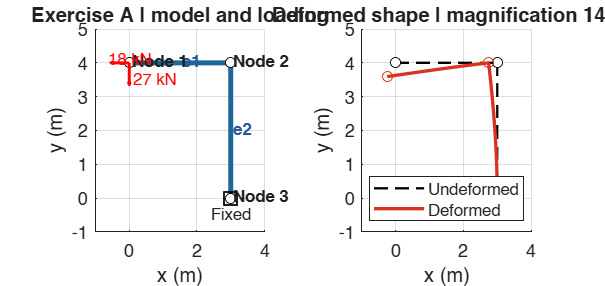

if makePlots
    plotFrame(nodes,elements,dofMap,d,elementData,qLocal,E,A,I, ...
        supportNodes,fixedDofs,deformationScale,'Exercise A');
    subplot(1,2,1); hold on;
    quiver(0,4,-0.55,0,0,'r','LineWidth',1.8,'MaxHeadSize',0.45);
    quiver(0,4,0,-0.65,0,'r','LineWidth',1.8,'MaxHeadSize',0.45);
    text(-0.62,4.15,'18 kN','Color','r');
    text(0.1,3.55,'27 kN','Color','r');
end

% Useful workspace variables: K, F, Kff, d, R, elementData,
% displacementTable, reactionTable, endForceTable, d1Analytical.

## 18. Classroom investigations and interpretation

Run the baseline model before experimenting. If loads or geometry change, update the analytical-check inputs consistently or skip that section. Suggested investigations: - Double E only: all displacements halve; reactions remain unchanged here. - Increase A only: identify the influence of axial flexibility. - Explain why full K has rigid-body modes but restrained Kff does not. - Reverse a member's node order and transform its local loads consistently; the global physical solution must remain unchanged. Exercise-specific discussion: - Why does a vertical load cause horizontal tip displacement? - Which contribution disappears if beam axial deformation is neglected? - Why is the tip rotation greater than the corner rotation?

Execute numbered sections in order, or run the whole file. The supporting local functions below are not additional exercise stages.

## LOCAL FUNCTIONS -- supporting routines

function [k,T] = frameElement(E,A,I,L,c,s)
% 2-node, 6-DOF Euler-Bernoulli plane-frame stiffness in LOCAL axes.
% Axial stiffness: EA/L. Bending stiffness: EI times powers of 1/L.
% Axial entries occupy rows/columns 1 and 4; bending uses 2,3,5,6.
% Off-diagonal terms couple end translations and rotations.
% T applies a coordinate-rotation block to each endpoint; the
% out-of-plane nodal rotation retains the same CCW sign.
    a = E*A/L;
    b = 12*E*I/L^3;
    g = 6*E*I/L^2;
    h = 4*E*I/L;
    j = 2*E*I/L;
    k = [ a  0  0 -a  0  0;
          0  b  g  0 -b  g;
          0  g  h  0 -g  j;
         -a  0  0  a  0  0;
          0 -b -g  0  b -g;
          0  g  j  0 -g  h];
    T = [ c  s  0  0  0  0;
         -s  c  0  0  0  0;
          0  0  1  0  0  0;
          0  0  0  c  s  0;
          0  0  0 -s  c  0;
          0  0  0  0  0  1];
end

function plotFrame(nodes,elements,dofMap,d,data,qLocal,E,A,I, ...
    supportNodes,fixedDofs,scale,caption)
% Bending uses Hermite interpolation plus the exact UDL particular solution.
% A straight line between displaced nodes would hide member curvature.
% The particular terms vanish at the ends (and their bending slopes vanish).
    nElem = size(elements,1);
    shape = cell(nElem,1);
    maxDisplacement = 0;
    for e = 1:nElem
        L = data(e).L;
        x = linspace(0,L,81);
        z = x/L;
        dl = data(e).dLocal;
        u = (1-z)*dl(1)+z*dl(4) + qLocal(e,1)*x.*(L-x)/(2*E*A);
        N1 = 1-3*z.^2+2*z.^3;
        N2 = L*(z-2*z.^2+z.^3);
        N3 = 3*z.^2-2*z.^3;
        N4 = L*(-z.^2+z.^3);
        v = N1*dl(2)+N2*dl(3)+N3*dl(5)+N4*dl(6) ...
            + qLocal(e,2)*x.^2.*(L-x).^2/(24*E*I);
        displacement = [data(e).c -data(e).s; data(e).s data(e).c]*[u;v];
        origin = nodes(elements(e,1),:).';
        xy = repmat(origin,1,numel(x)) + [data(e).c;data(e).s]*x;
        shape{e} = struct('xy',xy,'displacement',displacement);
        maxDisplacement = max(maxDisplacement,max(sqrt(sum(displacement.^2,1))));
    end
    span = max(max(nodes,[],1)-min(nodes,[],1));
    if scale <= 0
        scale = 0.12*span/max(maxDisplacement,eps);
    end
    figure('Color','w','Name',caption,'Position',[100 100 1100 520]);
    for panel = 1:2
        subplot(1,2,panel); hold on; grid on; axis equal;
        for e = 1:nElem
            xy = shape{e}.xy/1000;    % Display geometry in metres.
            h0 = plot(xy(1,:),xy(2,:),'k--','LineWidth',1.4);
            if panel == 1
                plot(xy(1,:),xy(2,:),'Color',[0.12 0.4 0.6],'LineWidth',3);
                midpoint = mean(xy,2);
                text(midpoint(1)+0.06,midpoint(2)+0.08,sprintf('e%d',e), ...
                    'Color',[0.15 0.35 0.6],'FontWeight','bold');
            else
                xyd = (shape{e}.xy+scale*shape{e}.displacement)/1000;
                h1 = plot(xyd(1,:),xyd(2,:),'-','Color',[0.85 0.2 0.12],'LineWidth',2);
            end
        end
        plot(nodes(:,1)/1000,nodes(:,2)/1000,'ko','MarkerFaceColor','w');
        for n = supportNodes.'
            if ismember(dofMap(n,3),fixedDofs)
                marker = 's'; label = 'Fixed';
            else
                marker = '^'; label = 'Pin';
            end
            plot(nodes(n,1)/1000,nodes(n,2)/1000,marker, ...
                'Color','k','MarkerSize',10,'LineWidth',1.5);
            text(nodes(n,1)/1000,nodes(n,2)/1000-0.13,label, ...
                'HorizontalAlignment','center','VerticalAlignment','top');
        end
        if panel == 1
            for n = 1:size(nodes,1)
                text(nodes(n,1)/1000+0.08,nodes(n,2)/1000+0.08, ...
                    sprintf('Node %d',n),'FontWeight','bold');
            end
            title([caption ' | model and loading']);
        else
            dd = reshape(d(dofMap.'),3,size(nodes,1)).';
            plot((nodes(:,1)+scale*dd(:,1))/1000, ...
                (nodes(:,2)+scale*dd(:,2))/1000,'o','Color',[0.85 0.2 0.12]);
            title(sprintf('Deformed shape | magnification %.1f',scale));
            legend([h0 h1],{'Undeformed','Deformed'},'Location','best');
        end
        xlabel('x (m)'); ylabel('y (m)');
        pad = 0.25*span/1000;
        xlim([min(nodes(:,1))/1000-pad,max(nodes(:,1))/1000+pad]);
        ylim([min(nodes(:,2))/1000-pad,max(nodes(:,2))/1000+pad]);
        set(gca,'FontSize',11);
    end
end